# Example 3: Streaming video in Normal mode

This example will show you how to run a model in normal and stream video data to the PC using UDP.

## Running in Normal mode

In the previous example the AR Drone 2.0 was run in External mode in order to receive the video stream in Simulink. The downside of External mode is the overhead introduced and the tcpip protocol which is not typipcally used for video streaming. This was dealt with by greatly reducing the resolution at which the video was streamed, in order to get a higher resolution video feed from the drone this example will show how to run the model in Normal mode and send the video feed to a second Simulink model using UDP.

## Receiving data using UDP

UDP is a simpler method of sending data than tcpip and comes with it's own limitations. In the case of the AR Drone 2.0 the maximum packet size for a single UDP packet is 15000 bytes. A single uncompressed image shot at 1280 * 720 pixels (interlaced) would therefor consist of over 122 maximum size UDP packets. While UDP is faster for this application than tcpip sending over 100 subsequent packages per frame will overburden the drone so down sampling will still be used to an extend for this example. As a single image will consist of many different packeges it is necessary to keep track of where each package belongs in the full image, to this end the full frame is devided into packages that are one byte smaller than the maximum size leaving room for a single byte to act as header. A model which can recombine these packages and show them as RGB video can be opened via :

open('Example3_Receiving_UDP_Video_In_Normal_Mode.slx');

Which will open up the model as seen below:

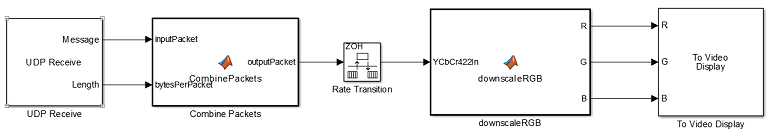

In this model we see a number of blocks:

**UDP Receive**

The UDP receive block is what allows the user to specify the network and UDP packet parameters desired for the UDP data transfer from the AR Drone 2.0 to this Simulink model. It has the following settings:

- Local IP Port: Set this to the port you wish to use for UDP trafic, this should be different from the ports used for any other protocols you wish to use in conjunction with this model (such as port 23 for telnet). The default value is 24000

- Remote IP adress: This is the IP adress of the AR Drone 2.0, by default set to '192.168.1.1'

- Receive buffer size (bytes): This buffer size is used to avoid data loss caused by buffer overflows. It is recommended to set this to no more than one packet size as that would cause addional delay.

- Maximum length for Message: This should be set equal to the size of the packet you wish to receive and no more than the amount of bytes permissible by the AR Drone 2.0 UDP packet size (15000)

- Data type for Message: This should be kept at uint8

- Output variable-size signal: This should be unchecked

- Sample time (seconds): This should be set at least as fast as the sample time with which the AR Drone 2.0 will be sending packages.

As the 'Ouput variable-size signal' option is unset the block will automatically provide an output for the constant 'length' variable which is then conveniently fed into the next block:

**Combine Packets**

The Combine Pakcets block takes packets from the UDP Receive block containing a single byte of header data and combines them into a single packet of user defined size. It has the setting:

- Full packet size: Set this to the number of bytes that the full input packet will contain. For example when using the front camera (1280 * 720 interlaced resolution meaning 2 bytes per pixel) and down sampling 5 times (in horizontal and vertical direction meaning a reduction in data of 25x) this value should be set to 73728 bytes.

Note that UDP is subject to package loss meaning that part of an image can be lost during transfer. This is visible to the user by part of the image lagging behind untill the next frame.

**Rate Transition**

The rate transition block allows for different sampling times of the input and output ports. As multiple packets need to be processed before a single image can be reconstructed the UDP Receive side of the model needs to run at a higher sample frequency than the video display side. It has the settings:

- Ensure data integrity during data transfer: Leave this option checked to reduce the amount of packet loss.

- Ensure deterministic data transfer (maximum delay): Leave this option checked such that data is only send to the next block in line after the user defined sample time has passed.

- Initial conditions: Can be left at 0.

- Ouput port sample time options: Set to specify to allow for control of the update rate of the video feed update frequency

- Output port sample time: Set to the update speed with which the video feed is caputured on the AR Drone 2.0 (for example 1/10 if the drone captures video at 10 Fps)

**Downscale RGB**

The Downscale RGB block can handle both downscaling and colorspace conversion to RGB. In this case we only use it for the color space conversion. It has the following settings:

- Input Image width: The width of the images contained within a fully recombined packet (for example 1280/5 when using the front camera and 5x down sampling).

- Input Image height: The height of the images contained within a fully recombined packet (for example 720/5 when using the front camera and 5x down sampling).

- Down scaling factor: The desired amount of down scaling applied to the input image (Leave this to 1 as the down scaling is allready happening on the drone and no further down scaling is necessary)

**To Video Display**

This block provides a lightweight, high performance display, which accepts RGB and YcbCr formatted videos. This block contains the following settings:

- View: Select the desired window size and whether it should open at the start of the simulation according to your needs.

- Input Color Format: Chose between RGB and YCbCr 4:2:2. As the camera output is YCbCr 4:2:2 and the desired color space is RGB both of these are valid settings depending on how the data can be sensibly transformed before passing it to the Video Display.

In this case it would have been possible to feed the YCbCr image into the Video Viewer but this would have still required transferring the one-dimensional input array containing the seperate pixel values into matrixes with the chroma and hue values. As the Downscale RGB block also takes care of the transformation to seperate red, green and blue intensity matrixes the RGB input mode is used.

## Running the video receive model

The model for receiving video is going to be running on the host PC and as such does not need to use the AR Drone configuration set and can be run using normal mode. Simply pless the 'Run' button in simulink and you are all set to receive video for which we will now set up the AR Drone 2.0.

## Streaming video using normal mode:

A second model is provided which will be run on the AR Drone 2.0 in normal mode. This reduces the overhead from external mode and allows the implementation of UDP instead of tcpip for video transfer. Open the model by evaluating the following MATLAB command:

open('Example3_Sending_UDP_Video_In_Normal_Mode.slx');

The model will appear as below:

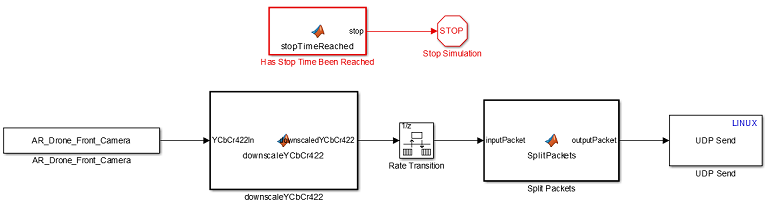

A number of blocks should be familiar from Example 2: Streaming video in external mode and from the previous model of this example. Some new blocks are introduced and will be explained below:

**Stop Time Reached**

This block will keep track of the run time of a model, if the run time is below the user specified stop time it will output '0', else it will output '1'. It has the following settings:

- Stop time [s]: This is the amount of seconds the model will run before this block outputs '1'

- Sample time [s]: This sets the sample time of this block, by setting it equal to the sample time of a different block they share a thread. As high accuracy is not required for this block the default is set to 0.1 [s], equal to the sample time of the front camera.

Note that if the AR Drone can not keep up with the model in real time due to the computational burden the 'stop' output will also be delayed.

**Stop Simulation**

When this block receives a non-zero input the simulation is stopped.

While the model will be executed in normal mode it will not be done by pressing the 'Run' button in Simulink but instead by using 'Build load and run' such that the model is running on the target hardware (AR Drone 2.0) instead of the Simulink PC. As such this is not a simulation and the simulation end time has no effect on the run time of the model, by sending a non-zero command to this block from the Stop Time Reached block the desired run time can be specified by the user.

**Split Packets**

This block splits an input array into packages of user specified maximum packet size, including a single byte as a header. It has one setting:

- Bytes per packet: The amount of bytes a single outgoing packet can contain. The default maximum value is 15000 bytes of which one byte is reserved as the header.

**UDP Send Linux**

This block will send a UDP packet to a target network adress and can be compiled to Linux targets, it has the following settings:

- Remote IP Adress: By default this is set to '192.168.1.2' as this is the default IP the PC receives when connecting to the AR Drone 2.0 wireless network.

- Remote IP Port: Set this to the port you wish to use for UDP trafic, this should be different from the ports used for any other protocols you wish to use in conjunction with this model (such as port 23 for telnet). The default value is 24000.

## Running the video send model

As the video send model will be running on the AR Drone it requires an AR Drone compatible configset. In the case of this example a different configset is used than before as the model will need to be run on the drone in normal mode instead of external mode. This means that the source files necessary for external mode communication are not required and that the model needs to be executed on the drone without waiting for any incoming tcpip 'start' packets. The example is allready set up to use the correct configuration set which you can see by pressing control + E. The Referenced configuration set name should be set to 'AR_Drone_ConfigSet_NOEXT'. Inside the Simulink window the simulation mode should allready be set to 'Normal'. With the 'Example3_Receiving_UDP_Video_In_Normal_Mode' model allready running you can simply press build or control + B to get the video streaming model running on the AR Drone 2.0 in normal mode. Once the process is complete you will see the video stream appear in the 'To Video Display' window of the 'Example3_Receiving_UDP_Video_In_Normal_Mode' model. Note that it is possible to stream video at a higher resolution or framerate due to the reduced overhead of normal mode and UDP compared to external mode and tcpip. After a certain amount of time the video stream will stop updating as the program on the AR Drone will terminate when the user specified Stop time is reached. You can then stop the 'Example3_Receiving_UDP_Video_In_Normal_Mode' model.